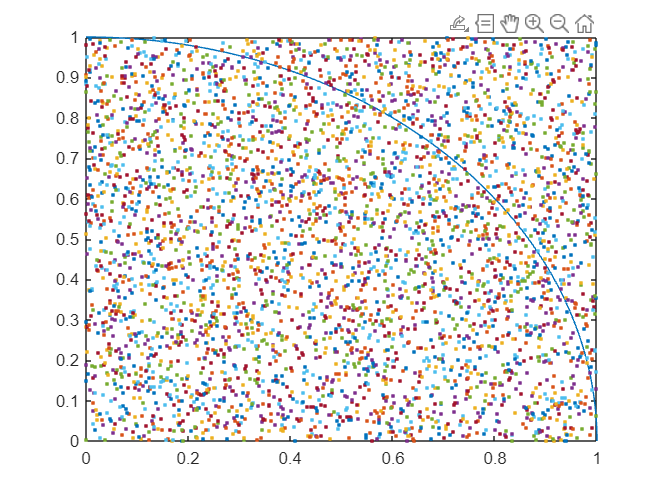

clc;clear;close all;
r=1;
theta=linspace(0,pi/2,100);
Circle=[r.*cos(theta);r.*sin(theta)];
plot(r.*cos(theta),r.*sin(theta))
hold on
n=0;
n_c=0;
pi_estimate=[];
temp1=1;
temp2=2;
while abs(temp1-temp2)>0.0002 || temp1==temp2
    point=[rand rand];
    plot(point(1),point(2),'.')
    n=n+1;
    if sum(point.^2)<=1
        n_c=n_c+1;
    end
    pi_estimate=[pi_estimate, n_c/n*4];
    temp2=pi_estimate(end);
    if length(pi_estimate)~=1
        temp1=pi_estimate(end-1);
    end
end

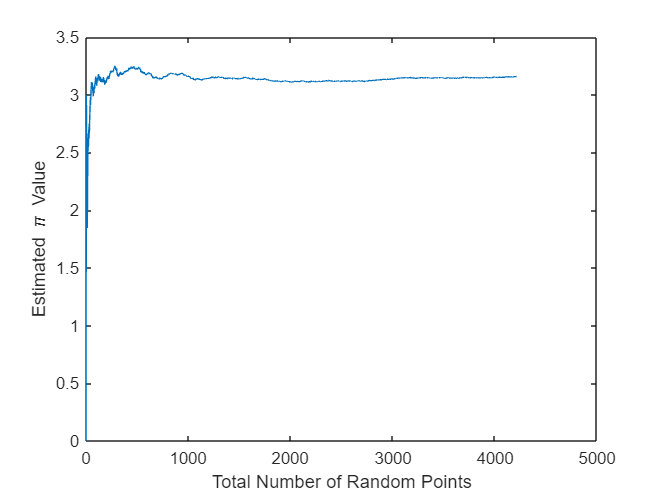

figure
plot(pi_estimate)
xlabel('Total Number of Random Points')
ylabel('Estimated \pi Value')

pi_final_estimate=pi_estimate(end)

pi_final_estimate = 3.1578